# Applying gradient descent for finding a good embedding

addpath functions

In here we test, whether finding a good embedding can be done by means of a gradient descent algorithm (see [https://www.codeproject.com/Articles/879043/Implementing-Gradient-Descent-to-Solve-a-Linear-Re).](https://www.codeproject.com/Articles/879043/Implementing-Gradient-Descent-to-Solve-a-Linear-Re).) Running a multivariant regression with gradient descent is implemented here through the function **main()**. Some test data is used.

% main();

We want to apply our embedding data to the gradient descent, not some test data though. So we have to modify the underlying functions (see bottom of this script) and the main script itself. As a cost function we want to use our previously declared **objective functions**.

Elapsed time is 0.012163 seconds.


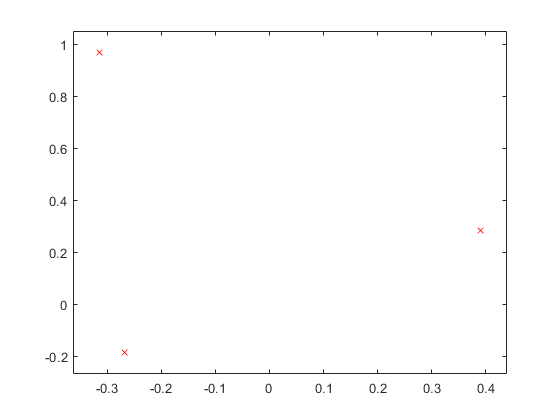

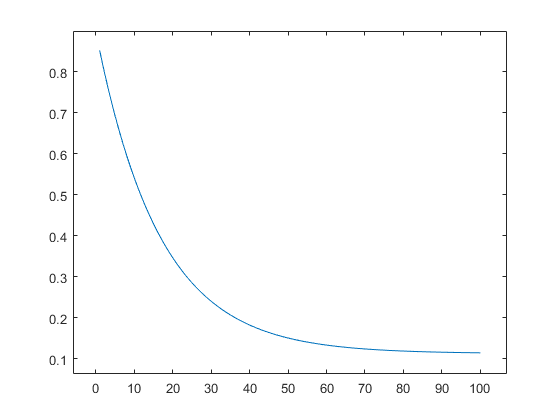

build("02");
build("06","Modus","gd");

Elapsed time is 0.033597 seconds.


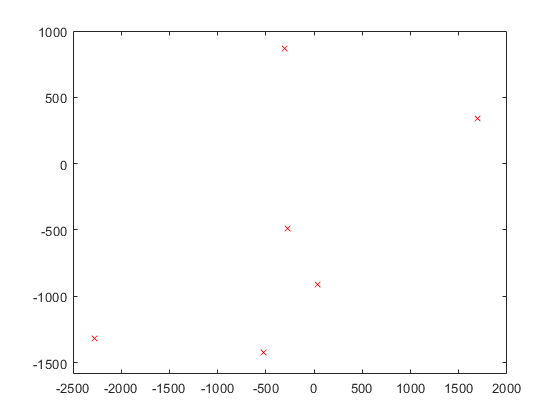

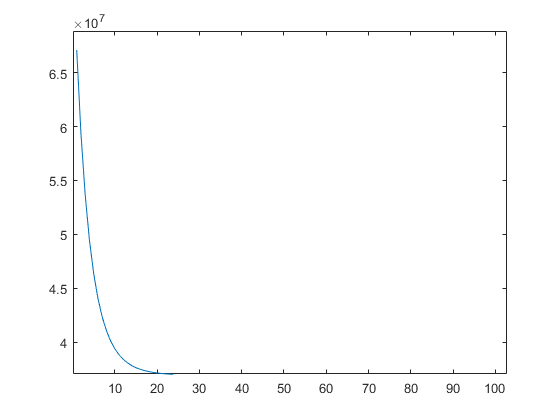

build("survey_theo","Modus","gd","InDegree",true);

The following code was (in parts) moved to the case statement in the function **build()**.

% plotData(pathData,0,0,0,1,1,1,0,1,0,0,0);
% figure;
% plot(nodes(:,1), nodes(:,2), 'rx', 'MarkerSize', 10);
% axis padded

% figure;
% plot(emb(:,1), emb(:,2), 'rx');
% axis padded

% learningRate = 0.01;
% repetition = 100;
% [embedding, ovHistory] = gradient(nodes(:,2:3), edges, learningRate, repetition);
% 
% figure;
% plot(embedding(:,1),embedding(:,2),'rx');
% % plot(min(embedding(:, 1)):max(embedding(:, 1)), embedding(1) + embedding(2) * (min(embedding(:,1)):max(embedding(:,1))));
% axis padded
% 
% % Plotting our cost function on a different figure to see how we did
% figure;
% plot(1:repetition, ovHistory);
% axis padded

% %
% 
% % Finally predicting the output of the provided input
% input = 5;
% if (normalization)
%     input = (input - maxX) / (maxX - minX);
% end
% output = embedding(1) + embedding(2) * input;
% disp(output);

## Functions

% function [ embedding, ovHistory ] = gradient( embedding, edges, learningRate, repetition )
%     %   Main algorithm that tries to minimize our cost functions
%     
%     % Getting the length of our dataset
%     n = size(embedding,1);
%     
%     % Creating a vector of zeros for storing our cost function history
%     ovHistory = zeros(repetition, 1);
%     
%     % Running gradient descent
%     currEmb = embedding;
%     tic
%     for i = 1:repetition
%         for nodeInd = 1:n
%             sum = [0 0];
%             currEdges = edges(find(edges(:,2)==nodeInd),:);
%             
%             for edgeInd = 1:size(currEdges,1)
%                 angle = currEdges(edgeInd,5);
%                 currP = [cos(angle) sin(angle)];
%                 sum = sum + embedding(currEdges(edgeInd,3),:) - embedding(nodeInd,:) - currP;
%             end
%             
%             currEmb(nodeInd,:) = embedding(nodeInd,:) + 2 * learningRate * sum;
%             
%             % Keeping track of the cost function
%             ovHistory(i) = objectiveFunction(embedding,edges);
%         end
%         embedding = currEmb;
%     end
%     toc
% end